clear
clf
clc
%Problem 4
%ToFind
%Thrust
%Dimensionless Thrust
%TSFC

%Turbofan without afterburner

% Input parameters

%Sea level conditions
T_sea = 288.16;
P_sea = 101325;
row_sea = 1.225;
H = 4572; %Given altitude
g = 9.81;
R = 287;
a = -0.0065;
H1 = 0;
cp = 1005;
T_a = T_sea + (a * (H - H1));
P_a = P_sea * ((T_a/T_sea)^(-g/(a*R)));
row_a = row_sea * ((T_a/T_sea)^(-(g/(a*R))-1));

%Given parameters
M_a = 0.93;
pi_c = 17;
pi_f = 2.3;
mdotc = 64.86;
%alpha = 0.5; %Varies from 0.5 to 1.5
delH = 75002.5;
T_o4 = 2800; %Combustor exit total temperature
gamma = 1.4;
y = 1;
for alpha = linspace(0.5,1.5,10)
%Diffuser
a_a = sqrt(gamma * R * T_a); % Speed of sound (m/s)
u_a = M_a * a_a; % Ramjet velocity (m/s)
T_oa = T_a * (1 + ((gamma - 1)/2)*(M_a)^2); % Total temperature at atm (K)
P_oa = P_a * ((1 + ((gamma - 1)/2)*(M_a)^2))^(gamma/(gamma - 1)); % Total pressure at atm (Pa)
row_a = P_a/(R * T_a); % Density (kg/m^3)
%A_in = (mdotc * (1 + alpha))/(row_a * u_a) % Diffuser inlet area (m^2)
P_o2 = P_oa;
T_o2 = T_oa;
P_o3 = (pi_c) * P_o2;
P_o4 = P_o3;
%Fan
P_o7 = (pi_f) * (P_o2);
T_o7 = T_o2 * (pi_f)^((gamma-1)/gamma);
%Fan nozzle
P_9 = P_a;
P_o9 = P_o7;
M_9 = sqrt((2/(gamma-1))*((P_o9/P_9)^((gamma-1)/(gamma)) - 1)); %exit mach of fan nozzle
T_o9 = T_o7;
T_9 = T_o9/(1 + (((gamma-1)/2) * (M_9)^2)); %(K)
a_9 = sqrt(gamma * R * T_9);
u_9 = M_9 * a_9;
%Turbine
tow_c = (pi_c)^((gamma - 1)/(gamma));
T_o3 = (T_o2) * (tow_c);
T_o5 = T_o4 - (T_o3 - T_o2) - ((alpha) .* (T_o7 - T_o2));
tow_t = (T_o5)/(T_o4);
tow_f = (T_o7)/(T_o2);
P_o5 = (P_o4) * ((tow_t)^((gamma)/(gamma-1)));
%Primary nozzle
P_8 = P_a;
P_o8 = P_o5;
M_8 = sqrt((2/(gamma-1))*((P_o8/P_8)^((gamma-1)/(gamma)) - 1)); %exit mach of nozzle
T_o8 = T_o5;
T_8 = T_o8/(1 + (((gamma-1)/2) * (M_8)^2)); %(K)
a_8 = sqrt(gamma * R * T_8);
u_8 = M_8 * a_8;
%Thrust and TSFC
F(1,y) = ((mdotc) * (u_8 - u_a)) + ((alpha .* mdotc) * (u_9 - u_a));
mdotf = ((mdotc * cp) * (T_o4 - T_o3))/(delH); %fuel mass flow rate (kg/s)
TSFC = mdotf./F;
%Non-Dimensional Thrust
nonF = F/(a_a * mdotc * (1+alpha));
y = y+1;
end

x = linspace(0.5,1.5,10);
F;
TSFC;
nonF;
Table_wab = table([x; TSFC; F; nonF])

Table_wab = 4×1 table
       Var1    
    ___________

    1×10 double
    1×10 double
    1×10 double
    1×10 double


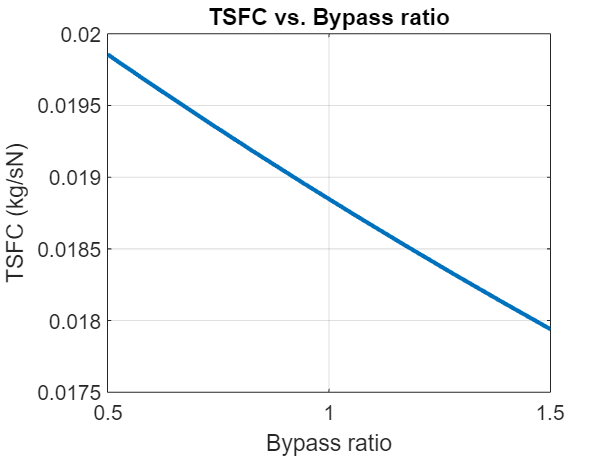

writetable(Table_wab, 'table_withoutab.csv', 'Delimiter',',')

plot(x,TSFC,'LineWidth',2);
xlabel('Bypass ratio');
ylabel('TSFC (kg/sN)');
title('TSFC vs. Bypass ratio');
grid on

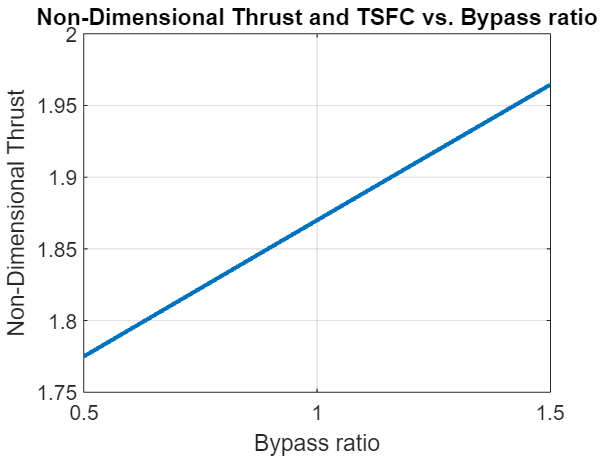

plot(x,nonF,'LineWidth',2);
xlabel('Bypass ratio');
ylabel('Non-Dimensional Thrust');
title('Non-Dimensional Thrust and TSFC vs. Bypass ratio');
grid on

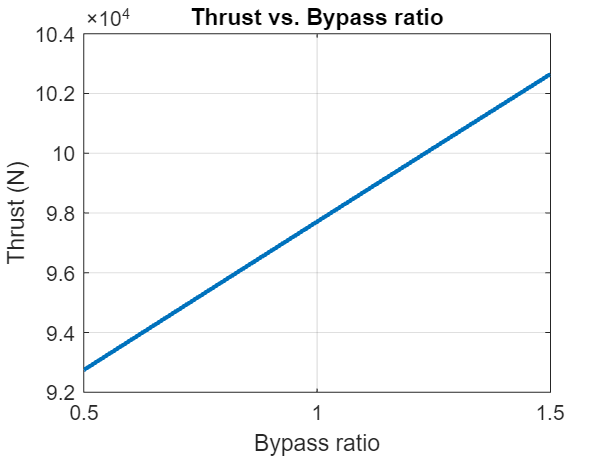

plot(x,F,'LineWidth',2);
xlabel('Bypass ratio');
ylabel('Thrust (N)');
title('Thrust vs. Bypass ratio');
grid on


%Turbofan with afterburner

% Input parameters

%Sea level conditions
T_sea = 288.16;
P_sea = 101325;
row_sea = 1.225;
H = 4572; %Given altitude
g = 9.81;
R = 287;
a = -0.0065;
H1 = 0;
cp = 1005;
T_a = T_sea + (a * (H - H1));
P_a = P_sea * ((T_a/T_sea)^(-g/(a*R)));
row_a = row_sea * ((T_a/T_sea)^(-(g/(a*R))-1));

%Given parameters
M_a = 0.93;
pi_c = 17;
pi_f = 2.3;
mdotc = 64.86;
%alpha = 0.5; %Varies from 0.5 to 1.5
delH = 75002.5;
T_o4 = 2800; %Combustor exit total temperature
gamma = 1.4;
T_o6 = 1777.78; %A/B exit total temperature
y = 1;
for alpha = linspace(0.5,1.5,10)
%Diffuser
a_a = sqrt(gamma * R * T_a); % Speed of sound (m/s)
u_a = M_a * a_a; % Ramjet velocity (m/s)
T_oa = T_a * (1 + ((gamma - 1)/2)*(M_a)^2); % Total temperature at atm (K)
P_oa = P_a * ((1 + ((gamma - 1)/2)*(M_a)^2))^(gamma/(gamma - 1)); % Total pressure at atm (Pa)
row_a = P_a/(R * T_a); % Density (kg/m^3)
%A_in = (mdotc * (1 + alpha))/(row_a * u_a) % Diffuser inlet area (m^2)
P_o2 = P_oa;
T_o2 = T_oa;
P_o3 = (pi_c) * P_o2;
P_o4 = P_o3;
%Fan
P_o7 = (pi_f) * (P_o2);
T_o7 = T_o2 * (pi_f)^((gamma-1)/gamma);
%Fan nozzle
P_9 = P_a;
P_o9 = P_o7;
M_9 = sqrt((2/(gamma-1))*((P_o9/P_9)^((gamma-1)/(gamma)) - 1)); %exit mach of fan nozzle
T_o9 = T_o7;
T_9 = T_o9/(1 + (((gamma-1)/2) * (M_9)^2)); %(K)
a_9 = sqrt(gamma * R * T_9);
u_9 = M_9 * a_9;
%Turbine
tow_c = (pi_c)^((gamma - 1)/(gamma));
T_o3 = (T_o2) * (tow_c);
T_o5 = T_o4 - (T_o3 - T_o2) - ((alpha) .* (T_o7 - T_o2));
tow_t = (T_o5)/(T_o4);
tow_f = (T_o7)/(T_o2);
P_o5 = (P_o4) * ((tow_t)^((gamma)/(gamma-1)));
%Afterburner
mdotf = ((mdotc * cp) * (T_o4 - T_o3))/(delH); %fuel mass flow rate (kg/s)
mdotfab = ((mdotc * cp) * (T_o6 - T_o5))/(delH); %A/B fuel mass flow rate (kg/s)
mdotft = ((mdotc * cp * T_a)/(delH))*((T_o6/T_oa) + (alpha * tow_f) - (1 + alpha));
%Nozzle
T_o8 = T_o6;
T_8 = (T_o8)./(1 + ((gamma-1)/2)*(M_8).^2);
a_8 = sqrt(gamma * R * T_8);
u_8 = M_8 .* a_8;
u8byu6 = sqrt((T_o6/T_a)*(1 - (1/((T_oa/T_a)*tow_c*tow_t)))/((T_oa/T_a)-1));
%Thrust
mdots = alpha * mdotc;
F_ab(1,y) = ((mdotc * u_a)*((u_8/u_a)-1)) + ((mdots * u_a)*((u_9/u_a)-1));
TSFC_ab = mdotft./F_ab;
A = (T_o6/T_a)/((T_oa/T_a) - 1);
B = ((T_oa/T_a)*(tow_c))*(1 - (((T_oa/T_a) * (T_a/T_o4))*(((tow_c)-1) + ((alpha) * (tow_f - 1)))));
C = sqrt((((T_oa/T_a)*(tow_f)) - 1)/((T_oa/T_a) - 1)) - 1;
nonThrust_ab(1,y) = (M_a * (sqrt(A * (1 - (1/B))) - 1)) + ((alpha * M_a) * C);
y = y+1;
end
nonThrust_ab

nonThrust_ab =     3.7506    3.8142    3.8776    3.9411    4.0044    4.0677    4.1309    4.1941    4.2572    4.3202


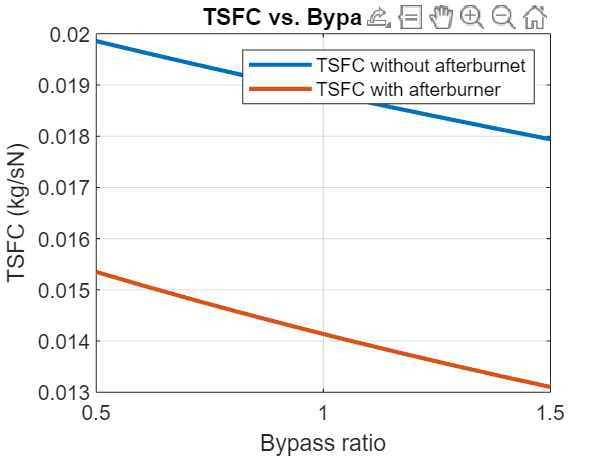

plot(x,TSFC,'LineWidth',2);
hold on
plot(x,TSFC_ab,'LineWidth',2);
xlabel('Bypass ratio');
ylabel('TSFC (kg/sN)');
title('TSFC vs. Bypass ratio');
grid on
legend('TSFC without afterburnet','TSFC with afterburner')
hold off

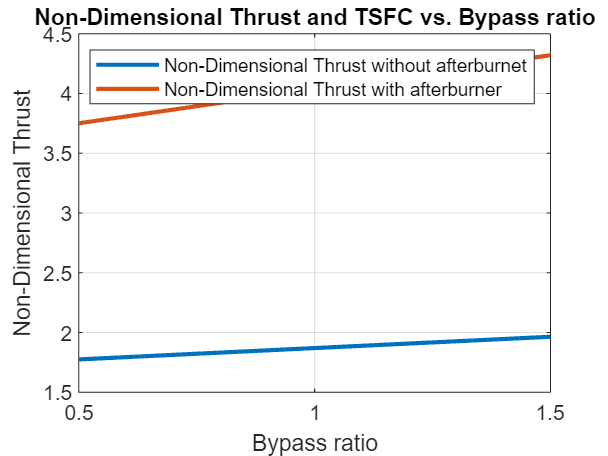


plot(x,nonF,'LineWidth',2);
hold on
plot(x,nonThrust_ab,'LineWidth',2);
xlabel('Bypass ratio');
ylabel('Non-Dimensional Thrust');
title('Non-Dimensional Thrust and TSFC vs. Bypass ratio');
grid on
legend('Non-Dimensional Thrust without afterburnet','Non-Dimensional Thrust with afterburner')
hold off

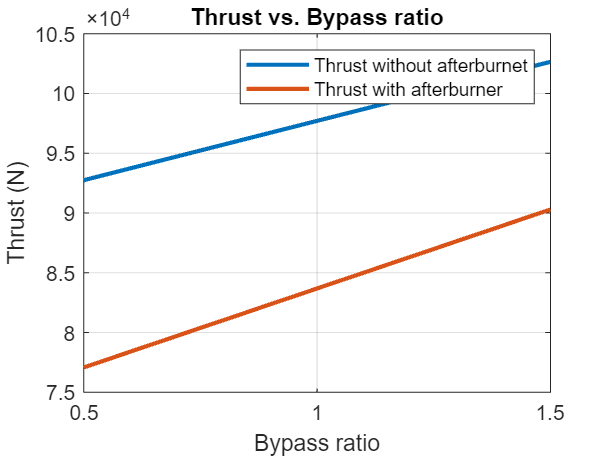


plot(x,F,'LineWidth',2);
hold on
plot(x,F_ab,'LineWidth',2);
xlabel('Bypass ratio');
ylabel('Thrust (N)');
title('Thrust vs. Bypass ratio');
grid on
hold off

legend('Thrust without afterburnet','Thrust with afterburner')